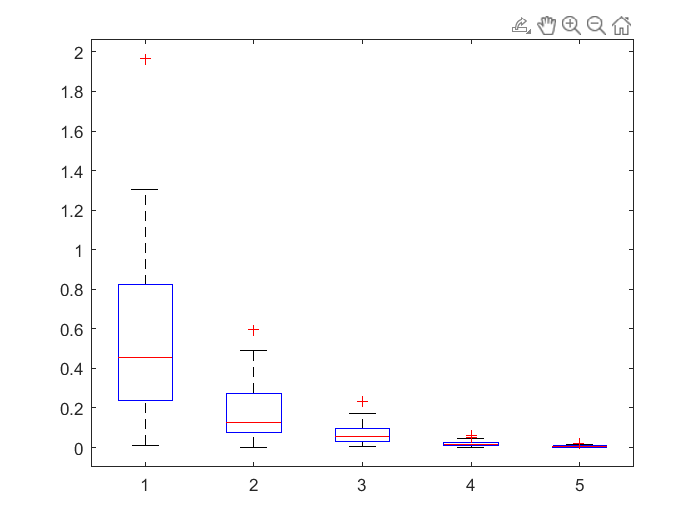

CovMatrix = [1.6250 -1.9486;-1.9486 3.8750];
mu = [1; 2];

% syms a b c
% eqns = [a^2 + b^2 == CovMatrix(1,1), a*c == CovMatrix(1,2), c^2 == CovMatrix(2,2)];
% vars = [a b c];
% [sola, solb, solc] = solve(eqns,vars);
% disp(solc)

c = sqrt(CovMatrix(2,2));
a = CovMatrix(1,2)/c;
b = sqrt(CovMatrix(1,1) - a*a);
d = 0;
A = [a b; c d];

j = 1;
error1 = zeros(1,100,5);
N1 = zeros(1,100,5);
for N = [10 100 1000 10000 100000]
    N1(:,:,j) = log10(N).*ones(1,100);
    cov_N = zeros(2,N);
    error = zeros(1,100);
    for p = 1:100
        K = randn(2,N); 
        points = zeros(2,N);
        for i = 1:N
            points(:,i) = mu + A*K(:,i);
        end
        ML_mu = sum(points,2)/N;
        prod_xy = zeros(1,N);
        for i = 1:N
            prod_xy(:,i) = points(1,i)*points(2,i); 
        end
        mu_x = ML_mu(1,:);
        mu_y = ML_mu(2,:);
        %disp(mu_x);
        mu_xy = sum(prod_xy)/N;
        cov_N(:,p) = (mu_xy - (mu_y*mu_x)) - CovMatrix(1,2);
        error(1,p) = norm(cov_N(:,p))/norm(CovMatrix(1,2));
    end
    error1(:,:,j) = error;
    j = j + 1;
end

error2 = reshape(error1,[1,500]);
N2 = reshape(N1,[1,500]);
figure;
boxplot(error2,N2);